# PRINCIPIOS Y APLICACIONES DEL MÉTODO MONTE CARLO  

## **Instrucciones**

- Se utilizaran archivos con extencion **.mlx** ya que son una manera mejorada de documentar los trabajos en ***Matlab*** (**NEW-->Live Script**).

- Se utilizaran **"Section Breaks"** para los cálculos en cada clase.

- Se ejecutará cada comando de cada capítulo mediante el botón ***"Run section"***.

- A la derecha, configurar la salida como "Output: Inline" para que se evalue las funciones y los gráficos debajo del código ejecutado.

## Clase 1

Clase 1. Lunes 02/09/24.

- **Experiencia 1: Estimar el número PI conociendo el tamaño de los fósforos y la distancia entre tres rectas paralelas.**

- Se procede a tirar 10 fósforos entre dos compañeros y se cuentan aquellos que intersectan alguna de las 3 líneas paraleles.

- El conteo para hasta que se contabilizan 500 fósforos arrojados.

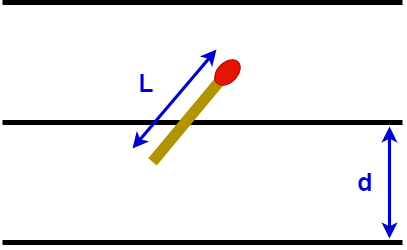

clear
Fosforos = [5 3 3 6 3 2 3 2 1 5 2 6 3 5 4 4 5 5 2 7 7 7 3 4 4 6 0 3 1 6 4 ...
    1 2 5 6 4 3 4 5 3 4 6 2 4 1 5 4 3 3 4];  
L = 4.25; % Longitud de los fósforos
d = 6.5; % Distancia entre las rectas paralelas

        3. Luego se aplica la siguiente fórmula:


$$\tilde{\pi} =\frac{2*L}{\tilde{p} *d}$$


        En donde $\tilde{p} =\frac{\sum \textrm{fósforos}\;\textrm{con}\;\textrm{intersecciones}}{\sum \;\textrm{fósforos}\;\textrm{tirados}}$

        Entonces:

p1 = 0; % Suma de fósforos que intersectan las líneas paraleles.
p2 = 500;  % Número total de fósforos tirados.
for i=1:length(Fosforos)
    p1 = p1 + Fosforos(i);
end
p = p1 / p2;
PI = (2 * L) / (p * d);
display(PI);

PI = 3.4413

        En nuestro caso, estimamos PI con el valor $PI=3.4413$.

        Evaluamos el histograma de la longitud de los fósforos:

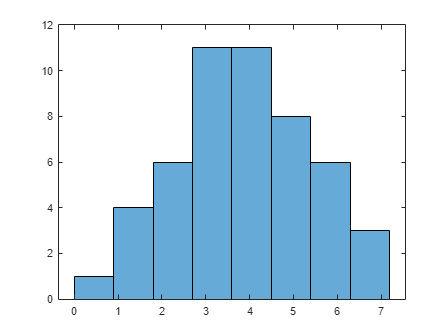

histogram(Fosforos, 8)

- **Experiencia 2: Estimar la longitud de una cuerda conociendo la longitud de lado de unas baldosas cuadradas.**

- Elegir y medir el lado ***d*** en un patrón de baldosas cuadradas.

- Arrojar ***N*** veces una cuerda de longitud desconocida ***L*** y contar, para cada intento, el número de veces que la cuerda intersecta cualquier línea de cualquier baldosa.

- Aplicar la siguiente relacion:

        
$$E\left(N\right)=\frac{\sum \textrm{Intersecciones}}{N}=\frac{4*L}{\pi *d}\Rightarrow L=\frac{\pi *d*\left(\sum \textrm{Intersecciones}\right)}{4*N}$$


        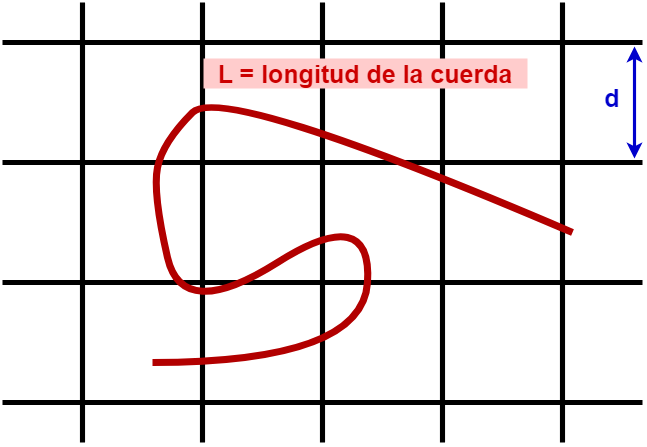

        En nuestro caso:

d = 20.3; % Longitud del lado de una baldosa cuadrada
cuerda = [7 9 8 7 8 8 8 8 13 6 10 7 9 10 7 6 8 6 9 8 9 9 9 7 10 10 9 9];
%intersecciones = 243;
intersecciones = 0;
for i=1:length(cuerda)
    intersecciones = intersecciones + cuerda(i);
end
N = 28;
LC = pi * d * intersecciones / (4 * N); % Longitud de la cuerda
display(LC);

LC = 133.2428

        En nuestro caso, estimamos LC con el valor $LC=138.3675 [cm]$.

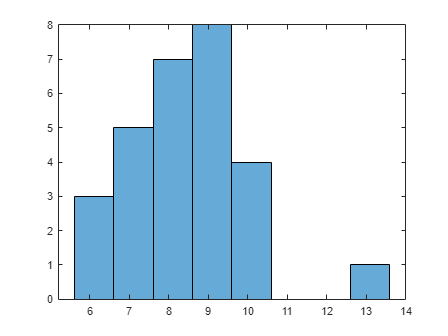

histogram(cuerda, 8)

## Clase 2

Clase 2. Viernes 06/09/24.

**Tablero de Galton.**

El tablero de Galton es el que se muestrea en las imagenes. En sus experiencias, Galton tiraba unas pelotitas al tablero y las juntaba en recipientes dispuestos debajo de cada uno de los sepraradores. Cada pelotita tiene la misma probabilidad de ir a  la derecha o a la izquierda cuando rebota en un separador. los recipientes colectan las pelotitas, y despues de N experiencias (siendo N muy grande), los recipientes tienen (aproximadamente) una forma de distribución Binomial.

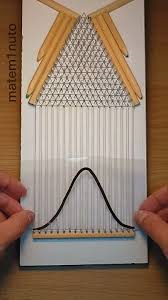                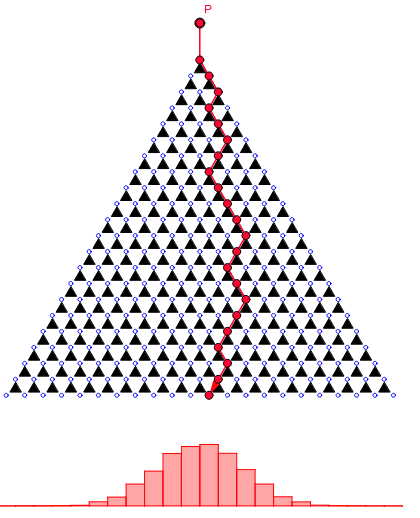

El código para simular este proceso es el siguiente:

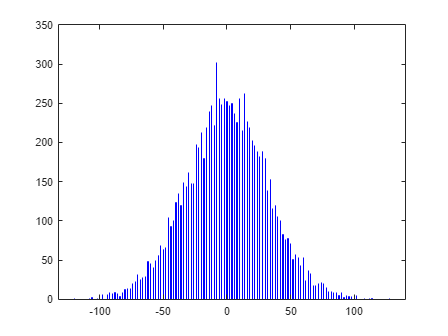

clear

N=1000; %Número de pisos del tablero de Dalton
p=0.5; % Probabilidad que una pelotita vaya a la izquierda

M=10000; % Nº de pelotitas arrojadas en la experiencia (se necesita que sea un número grande)

caida=[];

for k=1:M
    pos=0;
    for j=1:N
       if rand < p
           pos=pos-1;
       else
           pos=pos+1;
       end
    end
    caida=[caida pos];
end

histogram(caida,2*N+1,'FaceColor','b','EdgeColor','b')

**Presición en métodos computacionales.**

Se realiza este algoritmo sencillo:

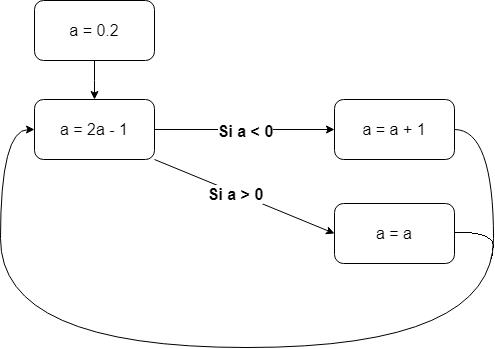

Manualmente se puede calcular que ***a*** efectúa un ciclo: $0.2 \rightarrow 0.4 \rightarrow 0.8 \rightarrow 0.6 \rightarrow 0.2$. El ciclo vuelve a empezar con 0.2. 

Sin embargo, si aplicamos el algoritmo mediante algún lenguaje de programación, vemos un resultado inesperadamente diferente:

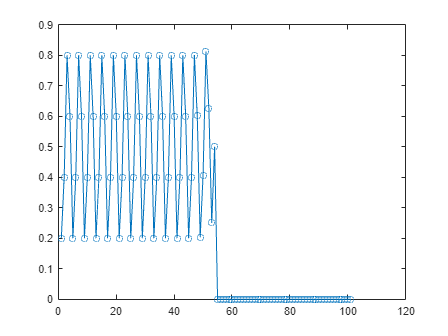

clear;
a1 = 0.2;
n1 = 100;
q1 = [];
q1(1) = 0.2;
for i = 2:n1 + 1
    a1 = 2 * a1 - 1;
    if a1<0  %probar con <=
        a1 = a1 + 1;
    end
    q1(i) = a1;
end
plot(1:n1+1, q1, 'o-');

¿Qué pasó? El problema son los decimales pasados a binario. Los decinales en binario se van acomulando de tal forma que llevado un cuerto número de iteraciones, estos ya no son depreciables y comienzan a influir en los resultados arrojados por el algoritmo. 

display(q1(45:60))

    0.2002    0.4004    0.8008    0.6016    0.2031    0.4062    0.8125    0.6250    0.2500    0.5000         0         0         0         0         0         0



Esto es muy importante tenerlo en cuenta en métodos numéricos que son evaluados computacionalmente como el de ***Montecarlo***. Esto se puede mejorar realizando un ***redodeo*** de decimales.

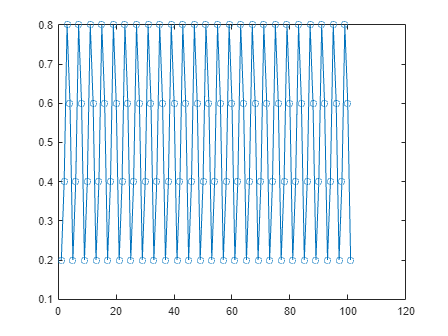

a2 = 0.2;
n2 = 100;
q2 = [];
q2(1) = 0.2;
for i = 2:n2 + 1
    a2 = 2 * a2 - 1;
    if a2<0  %probar con <=
        a2 = a2 + 1;
    end
    q2(i) = a2;
    a2 = round(a2, 1);
end
plot(1:n2+1, q2, 'o-');

display(q2(45:60))

    0.2000    0.4000    0.8000    0.6000    0.2000    0.4000    0.8000    0.6000    0.2000    0.4000    0.8000    0.6000    0.2000    0.4000    0.8000    0.6000



**Buffon 1.**

clear
N=10000 ;
F=0 ;
D=6.5 ;
L=4.25 ;

for i=1:N
    xA=rand*(-D);
    theta=rand*pi/2;
    xB=L*sin(theta)+xA;
    if xB>0
        F=F+1;
    end
end
      
Pest_B1=F/N ;
Preal_B1=(2*L)/(pi*D) ;
fprintf('El valor de "Pest_B1" es: %f\nEl valor de "Preal_B1" es: %f', Pest_B1, Preal_B1);

El valor de "Pest_B1" es: 0.419900
El valor de "Preal_B1" es: 0.416251

**Buffon 2.**

clear
N=10000 ;
F=0 ;
D=6.5 ;
L=4.25 ;
for i=1:N
    x=rand*D/2 ;
    tita=rand*pi/2 ;
    fun=L*sin(tita)/2 ;
    if x<fun 
        F=F+1 ;
    end
end
Pest_B2=F/N ;
Preal_B2=(2*L)/(pi*D) ;
fprintf('El valor de "Pest_B2" es: %f\nEl valor de "Preal_B2" es: %f', Pest_B2, Preal_B2);

El valor de "Pest_B2" es: 0.414200
El valor de "Preal_B2" es: 0.416251

**Fractal triangular.**

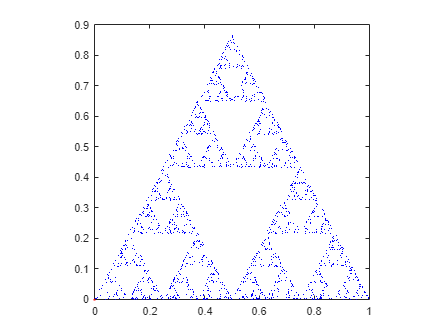

clear
N = 1000;
L = 1.0;
A =[0 0];
B = [L 0];
h = L*sqrt(3)/2;
C = [L/2 h];
% Q = [L/2 h/2];
Q = [0 0];
plot(Q(1,1),Q(1,2),'.r','MarkerSize',5)
    hold on
for i=1:N
    r = ceil(rand*3);
    if r==1 
        Q = (Q+A)/2;
    elseif r==2
        Q = (Q + B)/2;
        elseif r==3
        Q = (Q + C)/2;
    end
    plot(Q(1,1),Q(1,2),'.b','MarkerSize',1)
     %hold on
    %pause(0.001)
end
axis square

## Clase 3

Clase 3. Lunes 09/09/24.

Este algoritmo en MATLAB genera y visualiza una serie de recorridos** aleatorias** bidimensionales (en el plano XY) para `N=1000` eventos, con un **criterio de parada probabilístico**.

- **Inicialización**:

- `N=1000`: Define el número total de recorridos o trayectorias a simular.

- `lx=1` y `ly=1`: Definen los tamaños de las trayectorias en las direcciones `x` y `y`.

- `p=0.05`: Probabilidad que determina cuándo se detiene una recorrido aleatoria.

- `nc=[]`: Un vector vacío para almacenar la cantidad de pasos tomados por cada trayectoria.

- `x=0` y `y=0`: Inicializan las coordenadas de cada evento en el origen `(0,0)`.

**        2. Ciclo principal para cada caminante**:

- Se ejecuta un ciclo `for i=1:N` que representa los `1000` eventos.

- Dentro de este ciclo, la trayectoria aleatoria de cada evento empieza desde el origen `(0,0)` y continúa mientras la variable `d`, generada aleatoriamente con `rand`, sea mayor que la probabilidad `p=0.05`.

**        3. Caminata aleatoria**:

- En cada paso dentro del ciclo `while`, las coordenadas `x` y `y` se actualizan con valores aleatorios.

        Esto mueve el punto aleatoriamente dentro de un cuadrado de tamaño `lx` y `ly` en ambas direcciones. El uso de `rand` genera un número entre 0 y 1, y la fórmula     ajusta el valor para que esté centrado en `x` o `y` (por ejemplo, un paso puede ser de -0.5 a 0.5).

- Se dibuja cada nuevo punto con un marcador negro pequeño (`'k.'`) en el gráfico.

**        4. Criterio de parada**:

- El ciclo de la trayectoria (`while d > p`) se detiene cuando el valor aleatorio `d` generado por `rand` es menor o igual a `p=0.05`. Esto ocurre con una probabilidad del 5%, por lo que la trayectoria se detiene después de un número variable de pasos.

**        5. Visualización de la trayectoria**:

- Cada vez que el recorrido termina, el punto final del mismo se dibuja en azul (`'b.'`).

- El número de pasos `n` que tomó el recorrido se almacena en el vector `nc`.

**        6. Actualización del gráfico**:

- Cada 100 eventos (`mod(i,100)==0`), el gráfico se pausa brevemente (`pause(0.001)`) para que el usuario pueda ver la evolución del gráfico en tiempo real.

**Resumen:**

El algoritmo genera **1000 recorridos aleatorios bidimensionales**, donde cada recorrido comienza en el origen `(0,0)` y se mueve en pequeños pasos aleatorios dentro de una región de tamaño `lx` por `ly`. La trayectoria se detiene cuando una condición probabilística se cumple (cuando `rand <= p`). Cada trayectoria se dibuja en el gráfico, mostrando los puntos intermedios en negro y el punto final en azul. Además, se registra cuántos pasos ha tomado cada evento.

Este algoritmo podría representar, por ejemplo, la simulación de un proceso de difusión aleatoria o una trayectoria aleatoria de partículas en un plano en una desintegración.

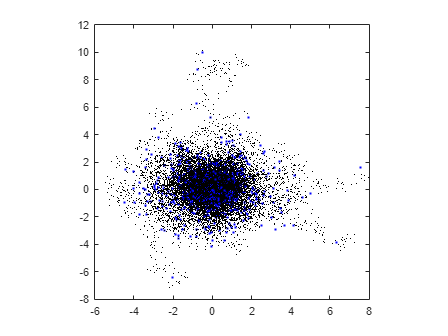

clear

N=1000;

lx=1;
ly=1;

p=0.05;
nc=[];
x=0;
y=0;
figure
plot(x,y,'ro')
hold on
axis square
for i=1:N
    x=0;
    y=0;
    d=rand;
    n=0;
    while d > p
   
        x=x+lx*rand-lx/2;
        y=y+ly*rand-ly/2;
        plot(x,y,'k.','MarkerSize',1)
       if mod(i,100)==0; pause(0.001); end
        n=n+1;    
             d=rand;
    end
    nc=[nc n];
    plot(x,y,'b.')
end